clear; clc; close all

Load a test image

% impath = ".\data\spiral\training\parkinson";
impath = ".\data\wetransfer_gaixo" % Trying our data :D

impath = ".\data\wetransfer_gaixo"

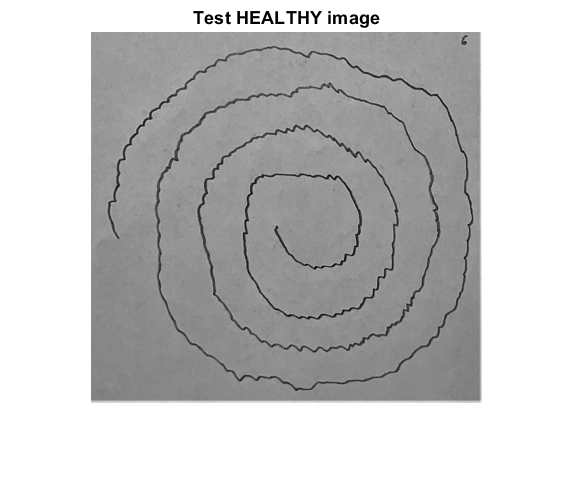

imname = "\PD_6.jpeg";
im = im2double(rgb2gray(imread(impath + imname)));
im = imresize(im, 0.25);
imshow(im, []); title('Test HEALTHY image')

[M,N] = size(im);

View image histogram

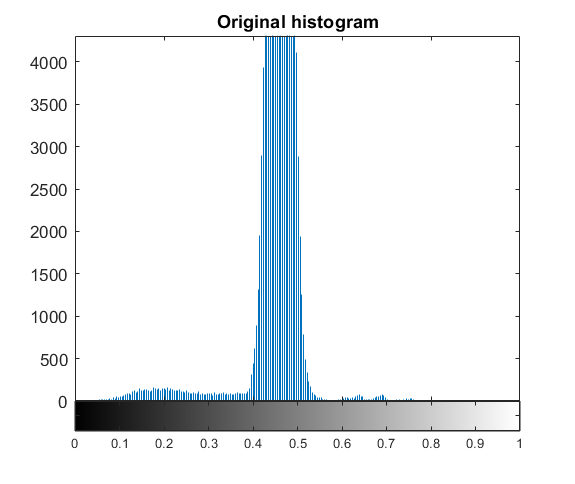

imhist(im);
title('Original histogram');

Apply Otsu's method thresholding to get the ROI of the stroke. Isolate the stroke.

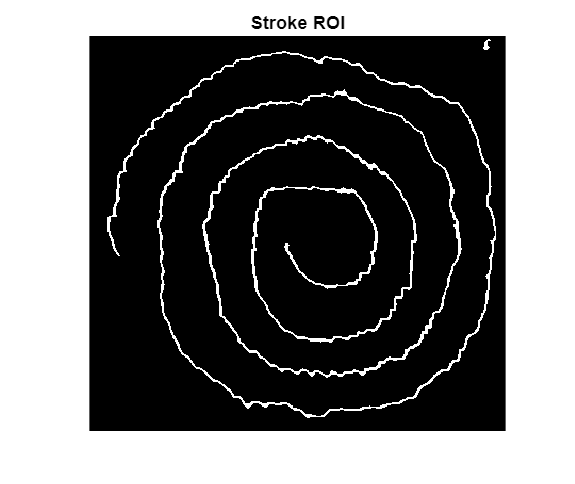

T = graythresh(im);
ROI = im < T;
ROI = imclose(ROI, strel("square", 4));
imshow(ROI); title('Stroke ROI')

Get the skeleton of the image and prune it

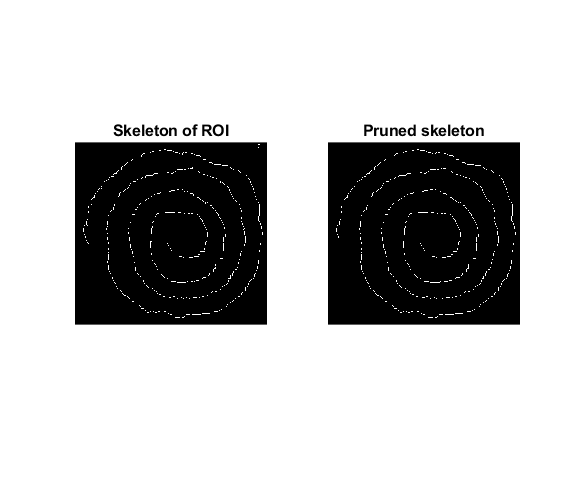

skel_im = bwmorph(ROI, 'skel', Inf);
subplot(121);imshow(skel_im); title('Skeleton of ROI')

% Remove single, isolated pixels from the image
pattern = zeros(3); pattern(2,2) = 1;
single_pixels = myhitnmiss(skel_im, pattern, 1); [spy, spx] = find(single_pixels);
skel_im(spy, spx) = 0;

pruned_skel_im = bwmorph(skel_im, 'spur', 10);
pruned_skel_im = imclose(pruned_skel_im, strel("square", 3));
subplot(122);imshow(pruned_skel_im); title('Pruned skeleton')

% Remove the salt again (it can appear after pruning)
single_pixels = myhitnmiss(pruned_skel_im, pattern, 1); [spy, spx] = find(single_pixels);
pruned_skel_im(spy, spx) = 0;

Prepare for the region growing procedure:

Get a starting position

% First we need to get one of the starting points. Hit or miss. No matter
% which one we take and the order of growing, because we will look at the
% spectral information of the signal.

% Find endpoints and get the outermost one (no particular reason, just to be
% consistent)
hits = bwmorph(pruned_skel_im, 'endpoints'); [endpy, endpx] = find(hits);

% Measure euclidean distance to center and take biggest (furthest point
% from center)
[M, N] = size(im);
C = round(0.5*[M, N]);
dists = sqrt((endpy-C(1)).^2 + (endpx-C(2)).^2); [~, biggest] = max(dists);
Y_init = endpy(biggest); X_init = endpx(biggest);


Start region growing.

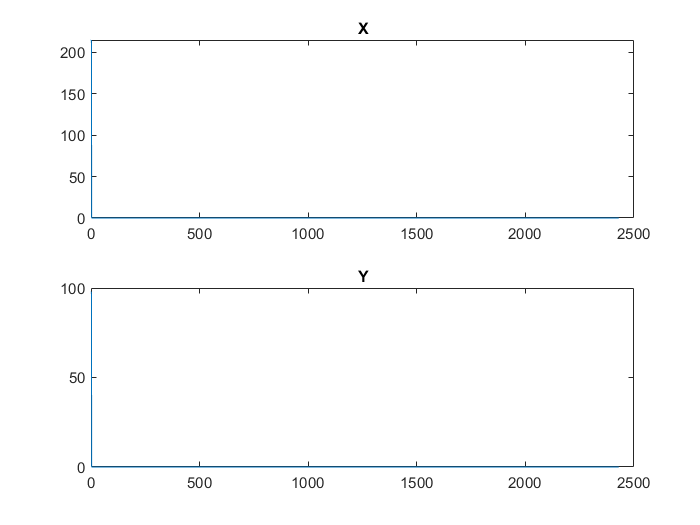

target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
dilater = strel('square', 3);

Xk = target_im;

canv_n = pruned_skel_im;
canv_n = padarray(canv_n, [1,1], 0);
[M, N] = size(im);
pointy = Y_init + 1; pointx = X_init + 1; % Add 1 because we padded !!!

endp_temp = [0,0,0;0,1,0;0,1,0];
salt_pattern = zeros(3); salt_pattern(2,2) = 1;

p = 0; ci = 1; ck = 1;
while ~isequal(canv_n, zeros(size(canv_n))) || ck > 5
    while (1)
        canv_n(pointy, pointx) = 0;
        p = find(canv_n(pointy-1:pointy+1, pointx-1:pointx+1));
        if isempty(p)
            break;
        end
        p = p(1);

        switch p
            case 1
                pointy = pointy - 1;
                pointx = pointx - 1;
            case 2
                pointx = pointx - 1;
            case 3
                pointy = pointy + 1;
                pointx = pointx - 1;
            case 4
                pointy = pointy - 1;
            case 6
                pointy = pointy + 1;
            case 7
                pointy = pointy - 1;
                pointx = pointx + 1;
            case 8
                pointx = pointx + 1;
            case 9
                pointy = pointy + 1;
                pointx = pointx + 1;
        end
        X_pts(ck, ci) = pointx;
        Y_pts(ck, ci) = pointy;

        ci = ci + 1;
    end
    ci = 1;

    % get new endpoint to continue with next segment
    ck = ck + 1;
    hits = myhitnmiss(canv_n, endp_temp, 8);

    % check if hitnmiss is empty
    if isequal(hits, zeros(size(hits))); break; end

    % Get new seed, set seed point to zero
    [pointy, pointx] = find(hits); pointy = pointy(1); pointx = pointx(1);
    canv_n(pointy, pointx) = 0;

    % delete possible salt (it will appear and haunt your dreams)
    single_pixels = myhitnmiss(canv_n, salt_pattern, 1); [spy, spx] = find(single_pixels);
    canv_n(spy, spx) = 0;


end

figure; hold on
for i = 1:size(X_pts, 1)
    subplot(211);plot(X_pts(i,:));title('X');
    subplot(212);plot(Y_pts(i,:));title('Y')
end